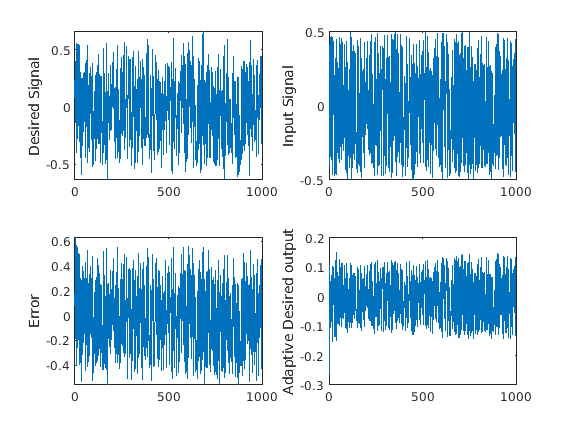

clc;
close all;
clear all;
N=1000;
t=[0:N-1];
ita=10^4;
I=ones(1,N);
R=ita*I;
input = xlsread('data_for_system_identification.xlsx','Sheet1');
%for output without noise 
x=input(:,1);
out=input(:,2);
w=zeros(1,N); 
for i=1:N
   y(i) = w(i)' * x(i);
   e(i) = out(i) - y(i);
   z(i) = R(i) * x(i);
   q = x(i)' * z(i);
   v = 1/(1+q);
   zz(i) = v * z(i);
   w(i+1) = w(i) + e(i)*zz(i);
   R(i+1) = R(i) - zz(i)*z(i);
end
for i=1:N
yd(i) = sum(w(i)' * x(i));  
end
subplot(221),plot(t,out),ylabel('Desired Signal'),
subplot(222),plot(t,x),ylabel('Input Signal'),
subplot(223),plot(t,e),ylabel('Error'),
subplot(224),plot(t,yd),ylabel('Adaptive Desired output');

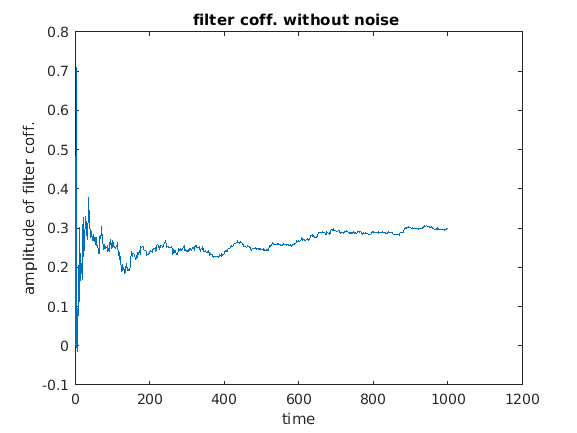

figure()
plot(w);xlabel('time');ylabel("amplitude of filter coff."),title("filter coff. without noise ");

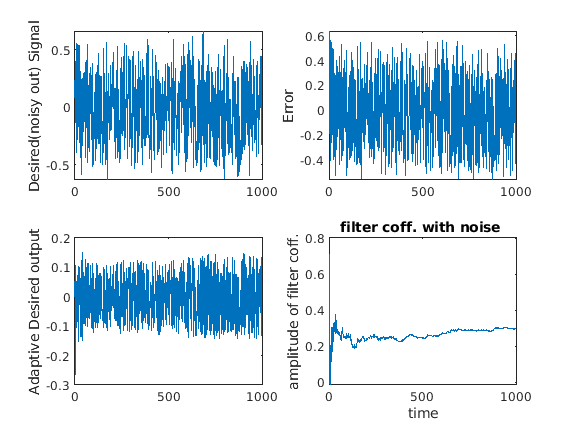

% for NOISY output 
noisy_out=input(:,3);
w1=zeros(1,N); 
for i=1:N
   y1(i) = w1(i)' * x(i);
   e1(i) = noisy_out(i) - y1(i);
   z1(i) = R(i) * x(i);
   q1 = x(i)' * z1(i);
   v1 = 1/(1+q1);
   zz1(i) = v1 * z1(i);
   w1(i+1) = w1(i) + e(i)*zz1(i);
   R(i+1) = R(i) - zz1(i)*z1(i);
end
for i=1:N
yd1(i) = sum(w1(i)' * x(i));
end
figure()
subplot(221),plot(t,noisy_out),ylabel('Desired(noisy out) Signal'),
subplot(222),plot(t,e1),ylabel('Error'),
subplot(223),plot(t,yd1),ylabel('Adaptive Desired output');
subplot(224),
plot(w);xlabel('time');ylabel("amplitude of filter coff."),title("filter coff. with noise ");

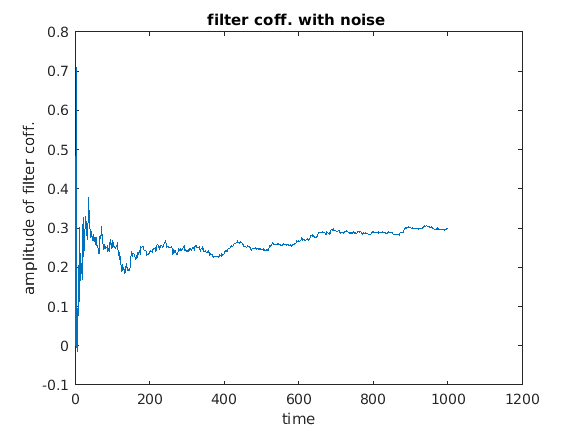

figure()
plot(w);xlabel('time');ylabel("amplitude of filter coff."),title("filter coff. with noise ");